# Reeds-Shepp curves, Breadth-first search

The following code uses the RSC method in order to generate a graph consisting of nodes along the map; using motion primitives, which allow our car-like to move forward, have a right or left curve; in order to avoid the presence of cusps along the way.

Then using the BFS algortim finds the path to go from a starting point to an end point.

Finally highlight it in red on the map.

clear; clc; close all;

Definition of global parameters

global length_step radius_curve num_iterations points counter occupancy_matrix map sample_points connections curve_points legend
% Load map from a .mat file
% data = load('test/Files_mat/map_straight_with_roundabout.mat');
data = load('test/Files_mat/maps_5_1.mat');

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'invertedImage'}




% Extract map from data structure
% map = data.map_straight_with_roundabout';
map = data.invertedImage';

length_step = 5;            % Length of the step forward
radius_curve = 5;           % Bending radius for left and right curves
num_iterations = 500;       % Number of iterations
legend = 1;
curve_points = struct('start_node', [], 'end_node', [], 'points', {});
sample_points = [];
connections = [];

Start and goal point coordinates for the maps

% %% maps_5_1
Qs = [30, 80];
Qg = [300, 190];            %228/162, 202/32  10/8      288/118, 298/188 8/6

%% map_straight_with_roundabout
% Qs = [50, 40];
% Qg = [415, 30];           %15/10
% Qg = [415, 35];           %20/15

Variable initialization

% Vector for points
points = zeros(((num_iterations + 1)^3), 2);
points(1, :) = Qs;

% Occupancy matrix
occupancy_matrix = zeros(size(map));
occupancy_matrix(Qs(1), Qs(2)) = 1;         % Mark start point as visited
occupancy_matrix(map == 0) = 1;             % Mark cells with obstacles as visited

% Point counter
counter = 1;

% Queue for points to explore
queue = [Qs, 0, 1];         % [x, y, angle, iteration]

Plot initialization

figure;
imshow(map');
hold on;
% Plotting the start and goal points on the map
plot(Qs(1), Qs(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Start point');                      % Start point (red)
plot(Qg(1), Qg(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Goal point');                      % Goal point (green)

Initiation of proceedings from start point through which it constructs the graph using the RSC method.

while ~isempty(queue)
    % Extract the current point from the queue
    current_point = queue(1, 1:2);
    current_angle = queue(1, 3);
    iteration = queue(1, 4);
    queue(1, :) = [];                   % Remove the item from the queue

    % Calculate new points and add them to the queue if not visited
    new_points = calculate_points(current_point, current_angle, iteration);
    queue = [queue; new_points];                % Add new points to the queue
end

Adding the final notes on the plot figure

title('Primitive Reed-Sheep Curves Iterative');
xlabel('X');
ylabel('Y');
axis equal;
grid on;

Calculates the adjacency matrix having in input the nodes and a vector indicating the connections between the nodes

sample_points = [Qs; sample_points];
adjacency_matrix = create_adjacency_matrix(sample_points, connections);

Find the path using BFS from a start point to an end point

[parent, current] = find_path_BFS(adjacency_matrix, sample_points, Qs, Qg);

Plots the previously obtained path

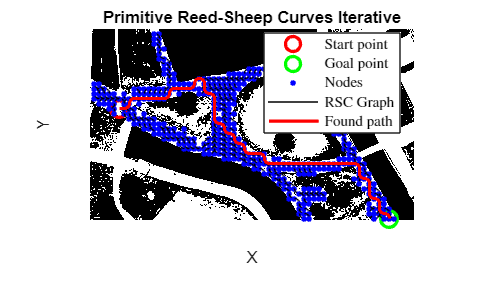

[optimal_path, collected_points] = reconstruct_path(parent, current, sample_points);

From the smooth path it calculates the coordinates to be given input to the controller

All velocity bounds have been satisfied


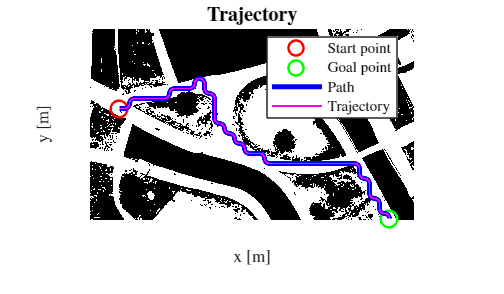

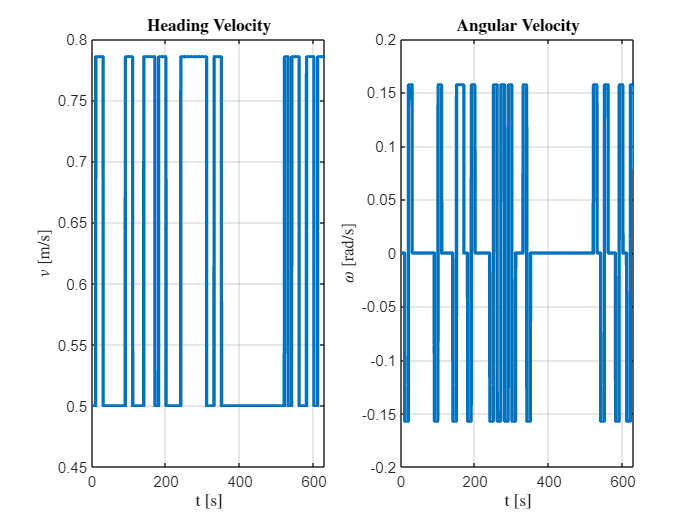

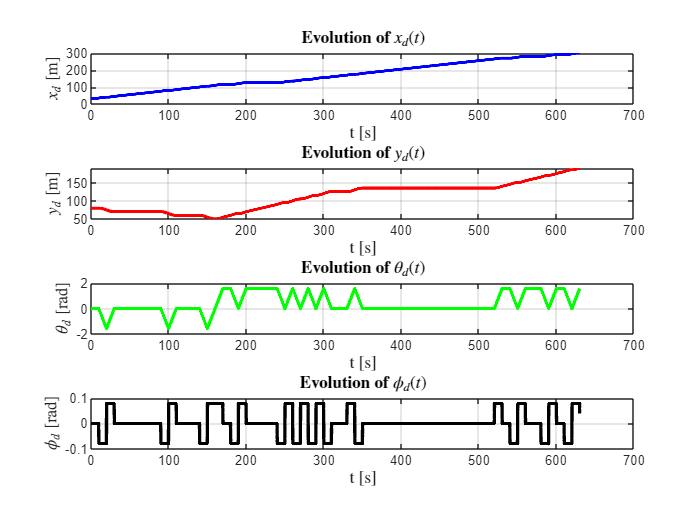

[xd, yd, thetad, phid] = des_trajectory(collected_points);

## FUNCTIONS

**Function to construct the graph using the RSC method.**

function new_points = calculate_points(current_point, current_angle, iteration)
    % Global variables
    global length_step radius_curve num_iterations points counter occupancy_matrix sample_points connections curve_points legend

    % Initialization of the new points
    new_points = [];

    % Condition of termination of recursion
    if iteration > num_iterations
        return;
    end

    % Calculation of the next point forward
    point_forward = round(current_point + length_step * [cos(current_angle), sin(current_angle)]);
    end_point_forward = point_forward;

    % Center of the circumference for the right turn
    center_right = current_point + radius_curve * [cos(current_angle - pi/2), sin(current_angle - pi/2)];

    % Center of circumference for left turn
    center_left = current_point + radius_curve * [cos(current_angle + pi/2), sin(current_angle + pi/2)];

    % Angles to generate quarter circles
    theta_right = linspace(current_angle + pi/2, current_angle, 101);
    theta_left  = linspace(current_angle - pi/2, current_angle, 101);

    % Calculation of the next point on the right
    x_right = center_right(1) + radius_curve * cos(theta_right);
    y_right = center_right(2) + radius_curve * sin(theta_right);
    end_point_right = round([x_right(end), y_right(end)]);

    % Calculation of the next point on the left
    x_left = center_left(1) + radius_curve * cos(theta_left);
    y_left = center_left(2) + radius_curve * sin(theta_left);
    end_point_left = round([x_left(end), y_left(end)]);

    % Adding points and curves to the plot only if they do not match previous points
    hold on;

    if is_within_bounds(end_point_forward) && ~is_point_visited(end_point_forward)
        x_points = round(linspace(current_point(1), end_point_forward(1), 300));
        y_points = round(linspace(current_point(2), end_point_forward(2), 300));
        if ~is_collision_forward(current_point, end_point_forward)
            counter = counter + 1;
            points(counter, :) = end_point_forward;
            sample_points = [sample_points; end_point_forward];
            occupancy_matrix(x_points, y_points) = 1;
            connections = [connections; current_point, end_point_forward];
            plot([current_point(1), end_point_forward(1)], [current_point(2), end_point_forward(2)], 'k-', 'LineWidth', 0.5, 'HandleVisibility','off');
            plot(end_point_forward(1), end_point_forward(2), 'b.', 'MarkerSize', 10, 'HandleVisibility','off');
            new_points = [new_points; end_point_forward, current_angle, iteration + 1];
            % In order to add to legend 
            if legend == 1
                plot(end_point_forward(1), end_point_forward(2), 'b.', 'MarkerSize', 10, 'DisplayName', 'Nodes');
                plot([current_point(1), end_point_forward(1)], [current_point(2), end_point_forward(2)], 'k-', 'LineWidth', 0.5, 'DisplayName', 'RSC Graph');
                legend = 0;
            end
        end
    end

    if is_within_bounds(end_point_right) && ~is_point_visited(end_point_right)
        if ~is_collision_curve(x_right, y_right)
            counter = counter + 1;
            points(counter, :) = end_point_right;
            sample_points = [sample_points; end_point_right];
            occupancy_matrix(round(x_right), round(y_right)) = 1;
            connections = [connections; current_point, end_point_right];
            plot(x_right, y_right, 'k-', 'LineWidth', 0.5, 'HandleVisibility','off');
            plot(x_right(end), y_right(end), 'b.', 'MarkerSize', 10, 'HandleVisibility','off');
            new_points = [new_points; end_point_right, current_angle - pi/2, iteration + 1];
        
            % Save the right corner points
            curve_points(end+1).start_node = current_point;
            curve_points(end).end_node = end_point_right;
            curve_points(end).points = [x_right', y_right'];
        end
    end

    if is_within_bounds(end_point_left) && ~is_point_visited(end_point_left)
        if ~is_collision_curve(x_left, y_left) 
            counter = counter + 1;
            points(counter, :) = end_point_left;
            sample_points = [sample_points; end_point_left];
            occupancy_matrix(round(x_left), round(y_left)) = 1;
            connections = [connections; current_point, end_point_left];
            plot(x_left, y_left, 'k', 'LineWidth', 0.5, 'HandleVisibility','off');
            plot(x_left(end), y_left(end), 'b.', 'MarkerSize', 10, 'HandleVisibility','off');
            new_points = [new_points; end_point_left, current_angle + pi/2, iteration + 1];
            
            % Save the left corner points
            curve_points(end+1).start_node = current_point;
            curve_points(end).end_node = end_point_left;
            curve_points(end).points = [x_left', y_left'];
        end
    end
end

Function to check if a point has already been visited

function visited = is_point_visited(point)
    global occupancy_matrix
    visited = false;
    if occupancy_matrix(point(1), point(2)) == 1
        visited = true;
    end
end

Function to check if a point is within the limits of the matrix

function within_bounds = is_within_bounds(point)
    global occupancy_matrix
    within_bounds = point(1) > 0 && point(2) > 0 && point(1) <= size(occupancy_matrix, 1) && point(2) <= size(occupancy_matrix, 2);
end

Function to check whether the generated curves have collisions with obstacles (forward motion)

function collision_forward = is_collision_forward(current_point, end_point_forward)
    global map

    collision_forward = false;
    % Calculate points equidistant between start and end
    x_points = round(linspace(current_point(1), end_point_forward(1), 300));
    y_points = round(linspace(current_point(2), end_point_forward(2), 300));
    for i = 2:(length(x_points)-1)
        if map(x_points(i), y_points(i)) == 0
            collision_forward = true;
            break
        end
    end
end

Function to check whether the generated curves have collisions with obstacles (curves)

function collision_curve = is_collision_curve(x, y)
    global map

    collision_curve = false;
    for i = 2:(length(x)-1)
        if map(round(x(i)), round(y(i))) == 0
            collision_curve = true;
            break
        end
    end
end

**Function to calculate the adjacency matrix having in input the nodes and a vector indicating the connections between the nodes**

function adjacency_matrix = create_adjacency_matrix(nodes, connections)
    num_nodes = size(nodes, 1);
    adjacency_matrix = zeros(num_nodes);

    for i = 1:size(connections, 1)
        point_1 = connections(i, 1:2);
        point_2 = connections(i, 3:4);
        
        idx_1 = find(ismember(nodes, point_1, 'rows'));
        idx_2 = find(ismember(nodes, point_2, 'rows'));
        
        if ~isempty(idx_1) && ~isempty(idx_2)
            adjacency_matrix(idx_1, idx_2) = 1;
            adjacency_matrix(idx_2, idx_1) = 1;
        end
    end
end

**Function to find the path using BFS from a start point to an end point**

function [parent, current] = find_path_BFS(adjacency_matrix, sample_points, Qs, Qg)
    nodes       = sample_points;
    num_samples = size(nodes, 1);

    % Find indices of start and goal nodes in nodes array
    [~, Qstart_index] = min(pdist2(nodes, Qs));
    [~, Qgoal_index]  = min(pdist2(nodes, Qg));

    % BFS initialization
    queue   = Qstart_index;                 % Start with the index of the start node
    parent  = zeros(1, num_samples);
    visited = false(1, num_samples);
    visited(Qstart_index) = true;           % Mark start node as visited

    % BFS search
    while ~isempty(queue)
        current = queue(1);
        queue(1) = [];
        
        if current == Qgoal_index
            % Reconstruct the path from goal to start
            % Interpolate the path
            % Both are done in the main
            return;
        end
        
        % Explore neighbors (nodes connected to current)
        neighbors = find(adjacency_matrix(current,:) == 1);
        for i = 1:length(neighbors)
            if ~visited(neighbors(i))
                visited(neighbors(i)) = true;
                parent(neighbors(i)) = current;
                queue(end+1) = neighbors(i);
            end
        end
    end
end

**Function to plot the previously obtained path**

function [path, collected_points] = reconstruct_path(parent, goal, nodes)
    path = [];
    current = goal;
    while current ~= 0
        path = [current, path];
        current = parent(current);
    end
    collected_points = plot_path(path, nodes, 'r');
end

Function to plot the lines between the various nodes and check if it is a curve

function collected_points = plot_path(path, nodes, color)
    global curve_points;
    collected_points = [];
    for i = 1:length(path)-1
        start_node = path(i);
        end_node = path(i+1);
        
        % Check if there is a curve between these nodes
        curve_index = find_curve_index(nodes(start_node,:), nodes(end_node,:));
        if ~isempty(curve_index)
            curve = curve_points(curve_index).points;
            plot(curve(:,1), curve(:,2), 'Color', color, 'LineWidth', 2, 'HandleVisibility','off');
            % Append all points except the last one to avoid duplication
            if isempty(collected_points)
                collected_points = curve;
            else
                collected_points = [collected_points; curve(2:end, :)];
            end
        else
            straight_line_points(:,1) = linspace(nodes(start_node,1), nodes(end_node,1), 101);
            straight_line_points(:,2) = linspace(nodes(start_node,2), nodes(end_node,2), 101);
            plot(straight_line_points(:,1), straight_line_points(:,2), 'Color', color, 'LineWidth', 2, 'HandleVisibility','off');
            % Append all points except the last one to avoid duplication
            if isempty(collected_points)
                collected_points = straight_line_points;
            else
                collected_points = [collected_points; straight_line_points(2:end, :)];
            end
        end
    end
    plot(straight_line_points(:,1), straight_line_points(:,2), 'Color', color, 'LineWidth', 2, 'DisplayName', 'Found path');
    leg = legend('show');
    set(leg, 'Interpreter','latex', 'fontsize', 9,'Location', 'best')
end

Function to check whether it is a curve and, if so, finds the intermediate points, and then reconstructs it

function index = find_curve_index(start_node, end_node)
    global curve_points;
    index = [];
    for i = 1:length(curve_points)
        curve = curve_points(i);
        if (isequal(curve.start_node, start_node) && isequal(curve.end_node, end_node)) || ...
           (isequal(curve.start_node, end_node) && isequal(curve.end_node, start_node))
            index = i;
            break;
        end
    end
end

**From the smooth path it calculates theta and phi and create desired trajectory to be given input to the controller **

function [xd, yd, thetad, phid] = des_trajectory(collected_points)

    global map;
    
    l = 0.5;
    
    % Extract x and y coordinates from the path
    x_s = collected_points(:, 1);
    y_s = collected_points(:, 2);
    
    % Number of points in the path
    N = length(x_s);
    
    % Initial Point
    x_i = x_s(1);
    y_i = y_s(1);
    theta_i = atan2(y_s(2) - y_s(1), x_s(2) - x_s(1));
    
    % Final Point
    x_f = x_s(end);
    y_f = y_s(end);
    theta_f = atan2(y_s(end) - y_s(end-1), x_s(end) - x_s(end-1));
    
    % Path visualization
    figure;
    imshow(map');
    hold on;
    plot(x_i, y_i, 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);                      % Start point (red)
    plot(x_f, y_f, 'go', 'MarkerSize', 10, 'LineWidth', 1.5);                      % Goal point (green)
    plot(x_s, y_s, 'b', 'lineWidth', 3);
    
    title('\textbf{Trajectory}','fontsize',12,'Interpreter','latex')
    xlabel('x [m]','Interpreter','latex','fontsize',10)
    ylabel('y [m]','Interpreter','latex','fontsize',10)
    grid on
    
    % Time Law Definition
    ti = 0;
    tf = 630;
    
    T = tf - ti;
    
    t = linspace(0, tf, N);
    
    % Temporal interpolation of the path
    x = interp1(linspace(0, 1, N), x_s, t / tf);
    y = interp1(linspace(0, 1, N), y_s, t / tf);
    
    % Calculation of velocities and accelerations using gradients
    x_dot = gradient(x, t);
    y_dot = gradient(y, t);
    x_ddot = gradient(x_dot, t);
    y_ddot = gradient(y_dot, t);
    
    v_tilde = sqrt(x_dot.^2 + y_dot.^2);
    omega_tilde = (y_ddot .* x_dot - x_ddot .* y_dot) ./ (x_dot.^2 + y_dot.^2);
    
    theta = atan2(y_dot./v_tilde, x_dot./v_tilde);
    phi = atan(l * (y_ddot .* x_dot - x_ddot .* y_dot) ./ (x_dot.^2 + y_dot.^2));
    
    % Since s_dot = 1 for a path linearly interpolated with respect to time
    s_dot = ones(size(t));
    
    v = v_tilde .* s_dot;
    omega = omega_tilde .* s_dot;
    
    v_max = 5;  % Velocity limit
    omega_max = 1;  % Angular velocity limit
    
    if (max(abs(v)) <= v_max && max(abs(omega)) <= omega_max)
        disp('All velocity bounds have been satisfied');
    else
        disp('Not all velocity bounds have been satisfied');
    end
    
    xd = timeseries(x, t);
    yd = timeseries(y, t);
    thetad = timeseries(theta, t);
    phid = timeseries(phi, t);
    
    % Visualization of the generated trajectory
    plot(x, y, 'm', 'lineWidth', 1.2)
    % Adding legend
    legend('Start point', 'Goal point', 'Path', 'Trajectory', 'fontsize', 9, 'Location', 'best', 'Interpreter','latex')
    
    % Heading velocity and angular velocity
    figure;
    subplot(1,2,1)
    plot(t, v, 'LineWidth', 2)
    title('\textbf{Heading Velocity}','FontSize',10,'Interpreter','latex')
    xlabel('t [s]','Interpreter','latex','FontSize',10)
    ylabel('$v$ [m/s]','Interpreter','latex','FontSize',10)
    grid on
    
    subplot(1,2,2)
    plot(t, omega, 'LineWidth', 2)
    title('\textbf{Angular Velocity}','FontSize',10,'Interpreter','latex')
    xlabel('t [s]','Interpreter','latex','FontSize',10)
    ylabel('$\omega$ [rad/s]','Interpreter','latex','FontSize',10)
    grid on
    
    % Create a new figure for the subplots
    figure;
    subplot(4,1,1);
    plot(t, x, 'b', 'LineWidth', 2);
    title('\textbf{Evolution of $x_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$x_d$ [m]','Interpreter','latex','FontSize',10);
    grid on;
    
    subplot(4,1,2);
    plot(t, y, 'r', 'LineWidth', 2);
    title('\textbf{Evolution of $y_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$y_d$ [m]','Interpreter','latex','FontSize',10);
    grid on;
    
    subplot(4,1,3);
    plot(t, theta, 'g', 'LineWidth', 2);
    title('\textbf{Evolution of $\theta_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$\theta_d$ [rad]','Interpreter','latex','FontSize',10);
    grid on;
    
    subplot(4,1,4);
    plot(t, phi, 'k', 'LineWidth', 2);
    title('\textbf{Evolution of $\phi_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$\phi_d$ [rad]','Interpreter','latex','FontSize',10);
    grid on;
    
end